# 智能优化算法

## 问题一

试计算一个有6个神经元的离散型Hopfield网络，其网络权值矩阵$E$和阈值向量$\theta$如下：

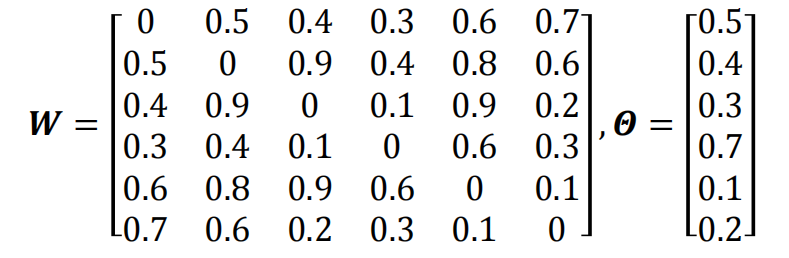

试确定网络最后的平衡状态。

答案：选取初值$\left(1,-1,1,-1,1,-1\right)$得到全局最优解$\left(-1,-1,-1,-1,-1,-1\right)$，能量为-9.6；选取初值$\left(-1,1,-1,1,-1,1\right)$得到局部最优解$\left(1,1,1,1,1,1\right)$，能量为-5.2

找不到现成的函数，只能硬干了。

% 丫的，抄这坨东西块累死了
W=[0 0.5 0.4 0.3 0.6 0.7;
    0.5 0 0.9 0.4 0.8 0.6;
    0.4 0.9 0 0.1 0.9 0.2;
    0.3 0.4 0.1 0 0.6 0.3;
    0.6 0.8 0.9 0.6 0 0.1;
    0.7 0.6 0.2 0.3 0.1 0];
theta=[0.5;0.4;0.3;0.7;0.1;0.2];
% 全局最优；局部最优
initial_value=[1 -1 1 -1 1 -1;-1 1 -1 1 -1 1]';
[E,final_state]=hopfield(W,theta,initial_value)

E = -9.6000

final_state =     -1
    -1
    -1
    -1
    -1
    -1


这次试一下暴力求解所有极值点

[E,final_state]=hopfield(W,theta)

E =    -9.6000
   -5.2000


final_state =     -1     1
    -1     1
    -1     1
    -1     1
    -1     1
    -1     1


倒是没啥问题，很稳定。

看看书上的例题10-1

答案：选取初值$\left(-1,1,-1,1,-1,1,-1,1\right)$得到全局最优解$\left(1,1,1,1,1,1,1,1\right)$，能量为-15.165；选取初值$\left(1,-1,1,-1,1,-1,1,-1\right)$得到局部最优解$\left(-1,-1,-1,-1,-1,-1\right)$，能量为-7.564998

% 书本例题10-1，这坨东西更大只，太恶心了，手要断了！！！
W=[0 0.55 0.45 0.33 0.63 0.78 0.24 0.17;
    0.55 0 0.91 0.47 0.58 0.61 0.30 0.22;
    0.45 0.91 0 0.10 0.19 0.26 0.77 0.53;
    0.33 0.47 0.10 0 0.66 0.32 0.14 0.05;
    0.63 0.58 0.19 0.66 0 0.15 0.70 0.065;
    0.78 0.61 0.26 0.32 0.15 0 0.81 0.15;
    0.24 0.30 0.77 0.14 0.70 0.81 0 0.23;
    0.17 0.22 0.53 0.05 0.065 0.15 0.23 0];
theta=[0.65 0.3 0.4 0.75 0.15 0.25 0.95 0.35]';
initial_value=[-1 1 -1 1 -1 1 -1 1;1 -1 1 -1 1 -1 1 -1]';
[E,final_state]=hopfield(W,theta,initial_value)

E =   -15.1650
   -7.5650


final_state =     -1     1
    -1     1
    -1     1
    -1     1
    -1     1
    -1     1
    -1     1
    -1     1


watermelon，多次运行后发现最终状态反了，能量倒没啥毛病。。。。搞不懂，十有二百九十八是书错了吧🐶

## 问题二

建立图10-15给出的二分图的最优化Hopfield模型，写出其权值矩阵，并编程 求解该图给出的二分图问题，其中，分割1可作为初始解，分割2为最优解。

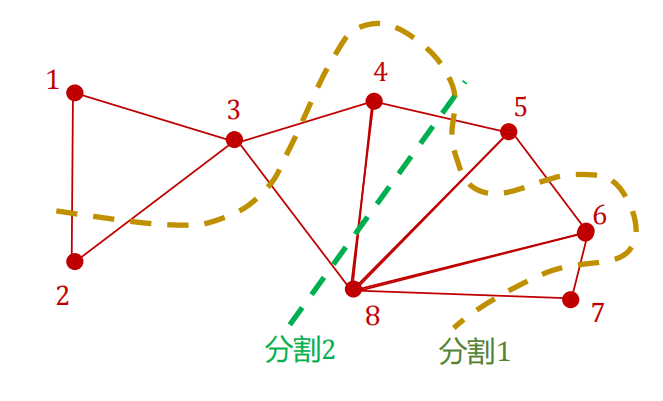

答案：分割线2

% ri！！！好大一坨矩阵
W=[0 .5 .5 -.5 -.5 -.5 -.5 -.5;
    .5 0 .5 -.5 -.5 -.5 -.5 -.5;
    .5 .5 0 .5 -.5 -.5 -.5 -.5;
    -.5 -.5 .5 0 .5 -.5 -.5 -.5;
    -.5 -.5 -.5 .5 0 .5 -.5 -.5;
    -.5 -.5 -.5 -.5 .5 0 .5 .5;
    -.5 -.5 -.5 -.5 -.5 .5 0 .5;
    -.5 -.5 .5 .5 .5 .5 .5 0];
theta=zeros(8,1);
[E,final_state]=hopfield(W,theta)

E =    -8.5000
   -8.5000


final_state =     -1     1
    -1     1
    -1     1
    -1     1
     1    -1
     1    -1
     1    -1
     1    -1


和答案相同。

## 问题三

试用二进制编码的遗传算法求下面优化问题的最优解：


$$\begin{array}{l}
\min \;f\left(x\right)=x_1 +x_2 +x_3 \\
8\le x_1 \le 14\\
3\le x_2 \le 7\\
5\le x_3 \le 10
\end{array}$$


已知3个初始个体为$x_1 =\left(9,5,7\right),x_2 =\left(10,6,8\right),x_3 =\left(12,4,9\right)$，要求进行两轮优化操作

先使用工具箱

% golbal optimization toolbox
x=ga(@(x) x(1)+x(2)+x(3),3,[],[],[],[],[8 3 5],[14 7 10])

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


x =      8     3     5


搞定。

突然感觉遗传算法用matlab不太好实现，而且这家伙也很简单啊，就不自己亲手撸代码了吧（主要是matlab的面向对象太阴间了，不是我想偷懒哈）

## 问题四

用一个20位的二值符号串表示和用简单遗传算法求解下式最小化的值:


$$f\left(x\right)={\left|\;x\right|}^{\frac{1}{2}} \sin \left(4\pi x\right),x\in \left\lbrack -2,2\right\rbrack$$


老规矩，能不动手就不动手，工具箱，启动！

答案：未知

x_opt=ga(@(x) (abs(x)).^(1/2)*sin(4*pi*x),1,[],[],[],[],-2,2)

ga stopped because the average change in the fitness value is less than options.FunctionTolerance.


x_opt = 1.8766

## 自定义函数

function [E,state]=hopfield(W,t,state_in)
% 计算Hopfield网络的平衡状态，异步模式
% input:
%   W,t：网络的权值（MXM矩阵）和阈值（MX1矩阵）
% output:
%   state：平衡状态返回值，MXN矩阵，N为最终状态个数

if nargin<3
    % 生成初始迭代向量组（100个初始状态向量），并去除重复的
    state_new=rand(length(t),100);
    state_new=(state_new>0.5)-(state_new<=0.5);
    state_new=unique(state_new.',"rows");
    state_new=state_new.';
else
    % 试验
    state_new=state_in;
end

% 迭代次数
irt=10000;

% 因为是随机更新一个状态，无法判断停止条件，要跑完所有循环，真是服了
for i=1:irt
    % 随机更新一个状态变量
    state_old=state_new;
    state_new=W*state_old-t;
    state_new=(state_new>=0)-(state_new<0);
    rand_choice=zeros(length(t),1);
    rand_choice(randi(length(rand_choice)))=1;
    state_new=state_new.*rand_choice+state_old.*(~rand_choice);
end
state_new=unique(state_new.',"rows");
state=state_new.';
E=diag(-1/2*state'*W*state+t'*state);
end